%%%此代码是为了对比11种图像清晰度评价函数在自己数据中的实用性，并最终选定一个作为最终评价函数
clear;
clc;
sharpness_quantization=nan(11,450);


%EOG(Energy Of Grad)
A=EOG(450);

time = 19.3885

sharpness_quantization(1,:)=A;


%Roberts
A=Roberts(450);

time = 19.8931

sharpness_quantization(2,:)=A;

%Tenengrad
A=Tenengrad(450);

time = 56.5801

sharpness_quantization(3,:)=A;

%Brenner
A=Brenner(450);

time = 17.5188

sharpness_quantization(4,:)=A;

%Variance
A=Variance(450);

time = 30.7232

sharpness_quantization(5,:)=A;

%Laplace 
A=Laplace(450);

time = 23.5320

sharpness_quantization(6,:)=A;

%DFT
A=DFT(450);

time = 101.5201

sharpness_quantization(7,:)=A;

%DCT
A=DCT(450);

time = 180.6256

sharpness_quantization(8,:)=A;

%entropy
A=entropy(450);

time = 64.7518

sharpness_quantization(9,:)=A;

%Range
A=Range(450);

time = 4.5809

sharpness_quantization(10,:)=A;

%vollaths
A=vollaths(450);

time = 18.0508

sharpness_quantization(11,:)=A;

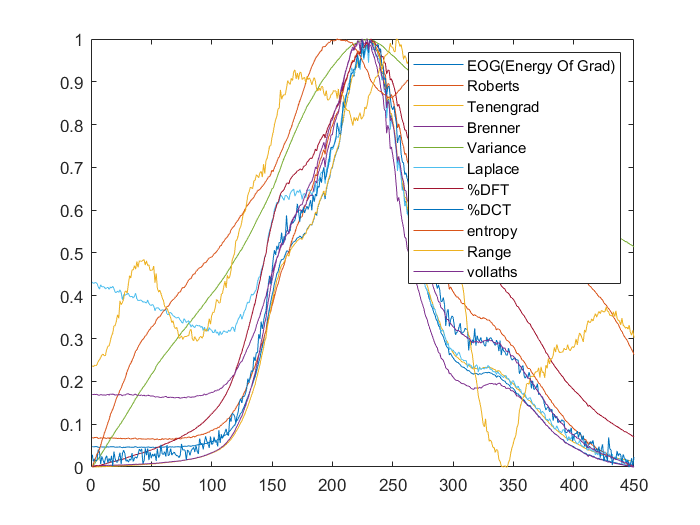

%plot
%load result.mat
plot(1:450,sharpness_quantization);
legend("EOG(Energy Of Grad)","Roberts","Tenengrad","Brenner","Variance","Laplace","%DFT","%DCT","entropy","Range","vollaths");


text(300,sharpness_quantization(1,300),"EOG(Energy Of Grad)");
text(350,sharpness_quantization(2,350),"Roberts");
text(131,sharpness_quantization(3,131),"Tenengrad");
text(286,sharpness_quantization(4,286),"Brenner");
text(400,sharpness_quantization(5,400),"Variance");
text(13,sharpness_quantization(6,13),"Laplace");
text(100,sharpness_quantization(7,100),"DFT");
text(272,sharpness_quantization(8,272),"DCT");
text(74,sharpness_quantization(9,74),"entropy");
text(41,sharpness_quantization(10,41),"Range");
text(73,sharpness_quantization(11,73),"vollaths");











